clear, clc, close all

% get data discribing DH parametre
data = getDHdata();
% get robot structure from data 
[robot,T_Ln_EE] = DH_Serial2robot(data);

plant.Q0 = [1;0;0;0]; % Base posture in Quaternion
plant.p0 = [0;0;0]; % Base position
plant.qm = [0;0;0;0;0]; % Joint variables [rad]
plant.omega = [0;0;0]; % derivative of base posture
plant.dp0 = [0;0;0]; % base velocity
plant.dqm = [0;0;0;0;0]; % Joint velocities

% external forces on base and joint
wF0=[0;0;0;0;0;0];
wFm=zeros(6,robot.n_q);    
%Joint torques
tauq0=zeros(6,1);
tauqm=zeros(robot.n_q,1);

history = [];
COMhis = [];
comhis = [];
X = p2X(plant);
dt = 0.01;
t = 0:dt:20;
tic
for i = t
    history = [history, X];
    for j = 1:5
        tauqm(j) = 0.5 * sin(0.3 * i);
    end
%     tauqm(1) = 0.5 * cos(0.3 * i);
%     tic
    X = stepForward(X,tauq0,tauqm,wF0,wFm,robot,dt);
%     toc
    global com
    comhis = [comhis,com];
end
T = toc

T = 9.1525

t_eachtime = T/length(t)

t_eachtime = 0.0046

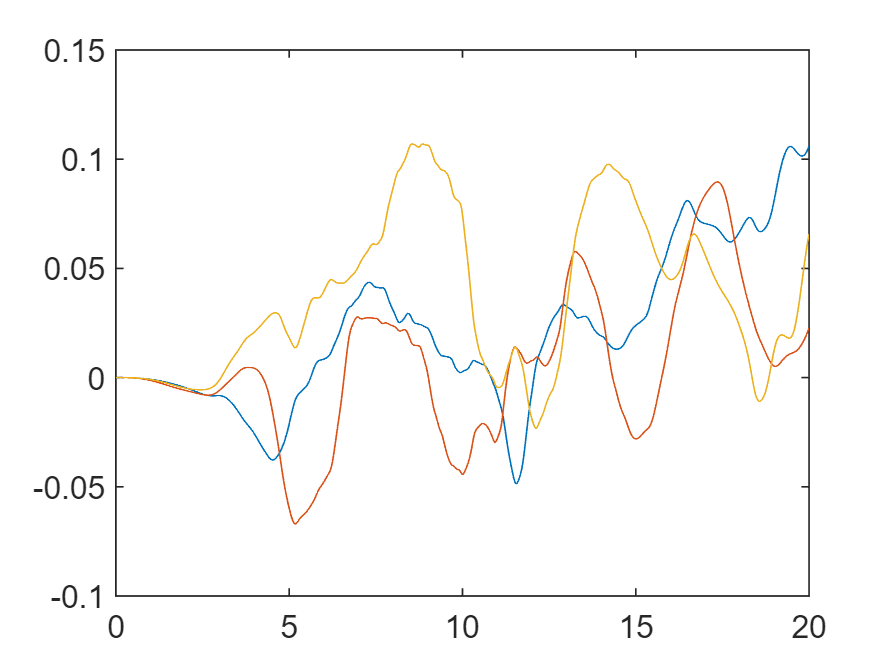

plot(t,history(5:7,:))

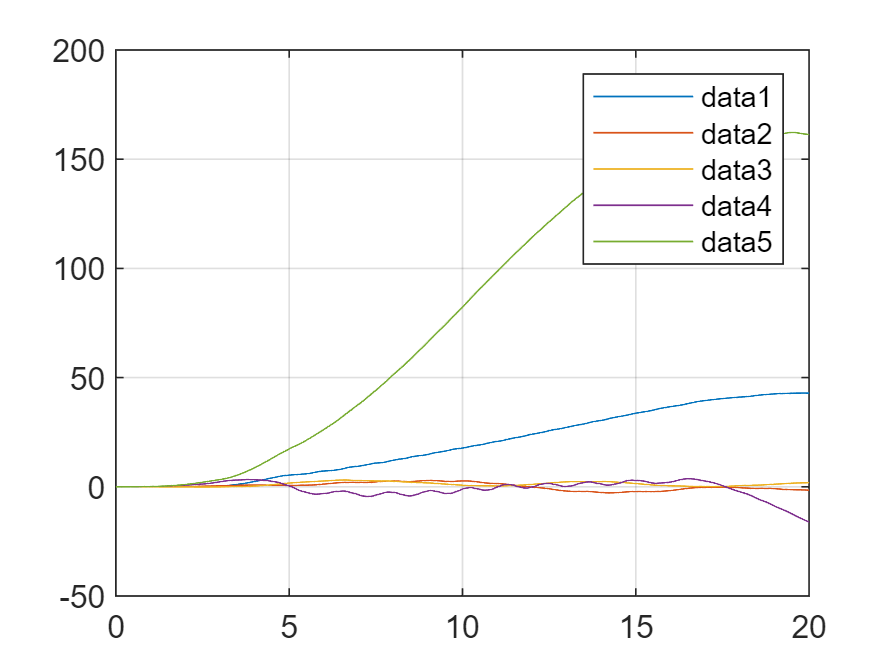


figure
plot(t,history(8:12,:))
legend('show')

grid on

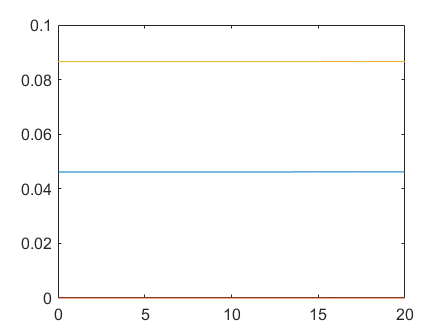


% figure
% plot(t,COMhis)

figure
plot(t,comhis)

function data = getDHdata()
    %--- Dimensions [m] ---%
    L0=50E-3;
    L1=125E-3;
    L2=144E-3;
    L3=47E-3;
    L4=142E-3;
    L5=80E-3;
    L6=70E-3;
    %--- Manipulator Definition ----%
    %Number of joints/links
    data.n=5;
    %First joint
    data.man(1).type=1;
    data.man(1).DH.d = L1;
    data.man(1).DH.alpha = pi/2;
    data.man(1).DH.a = 0;
    data.man(1).DH.theta=0;
    data.man(1).b = [0;L1/2;0];
    data.man(1).mass=2;
    data.man(1).I=diag([2,1,3])/10;
    %Second joint
    data.man(2).type=1;
    data.man(2).DH.d = 0;
    data.man(2).DH.alpha = 0;
    data.man(2).DH.a = sqrt(L2^2+L3^2);
    data.man(2).DH.theta=atan2(L2,L3);
    data.man(2).b = [cos(-data.man(2).DH.theta),-sin(-data.man(2).DH.theta),0;sin(-data.man(2).DH.theta),cos(-data.man(2).DH.theta),0;0,0,1]*[L3^2/2;L2^2/2 + L3*L2;0]/(L2 + L3);
    data.man(2).mass=2;
    data.man(2).I=diag([2,1,3])/10;
    %Third joint
    data.man(3).type=1;
    data.man(3).DH.d = 0;
    data.man(3).DH.alpha = 0;
    data.man(3).DH.a =L4;
    data.man(3).DH.theta=-atan2(L2,L3);
    data.man(3).b = [L4/2;0;0];
    data.man(3).mass=2;
    data.man(3).I=diag([2,1,3])/10;
    %Fourth joint
    data.man(4).type=1;
    data.man(4).DH.d = 0;
    data.man(4).DH.alpha = pi/2;
    data.man(4).DH.a = 0;
    data.man(4).DH.theta=pi/2;
    data.man(4).b = [0;0;-L5/2];
    data.man(4).mass=2;
    data.man(4).I=diag([2,1,3])/10;
    %Fifth joint
    data.man(5).type=1;
    data.man(5).DH.d = L5+L6;
    data.man(5).DH.alpha =-pi/2;
    data.man(5).DH.a = 0;
    data.man(5).DH.theta=-pi/2;
    data.man(5).b = [L6/2;0;0];
    data.man(5).mass=2;
    data.man(5).I=diag([2,1,3])/10;
    %First joint location with respect to base
    data.base.T_L0_J1=[eye(3),[0;0;L0];zeros(1,3),1];
    %Base-spacecraft mass and inertia
    data.base.mass=20;
    data.base.I=diag([2,1,3]);
    %End-Effector
    data.EE.theta=-pi/2;
    data.EE.d=0;
end



function X = p2X(plant)
% convert a plant structure to a state vector X
    X = [plant.Q0;   % Base posture in Quaternion
         plant.p0;  % base position
         plant.qm;   % Joint variables [rad]
         plant.omega; % base angular vel
         plant.dp0;  % base velocity
         plant.dqm];   % Joint velocities
end

function plant = X2p(X)
% convert a state vector X to plant structure
    plant.Q0 = X(1:4); % Base posture in Quaternion
    plant.p0 = X(5:7); % Base position
    plant.qm = X(8:12); % Joint variables [rad]
    plant.omega = X(13:15); % Base angle vel
    plant.dp0 = X(16:18); % base vel
    plant.dqm = X(19:end); % Joint velocities,19 to 23
end

function omega = dQ2Omega(Q,dQ)
% convert a quaternion(4x1) to omega(3x1)
% Q: 4x1 quaternion, the real part at the beginning
% dQ: 4x1 direvative of Q
% CAUTIOUS! 
% this function may lead to singularity if Q(0) == 0
    omega = 2 * (    ( Q(1)^2*eye(3) - Q(1)*SkewSym(Q(2:4)) +  Q(2:4)*Q(2:4)' )  /  Q(1)    ) * dQ(2:4);
end

function dQ = omega2dQ(Q,omega)
% convert angle velicity to quat
% see omega = dQ2Omega(Q,dQ)
%     dQ = 1/2 * [-Q(2:4)'  ;  Q(1)*eye(3) - SkewSym(Q(2:4)) ] * omega;
    % WATCH OUT, THE TRANSPPOSE MATTERS!!
    dQ = 1/2 * [-Q(2:4)'  ;  ( Q(1)*eye(3) - SkewSym(Q(2:4)) )' ] * omega;
end

function X_dot = DyX(X,tauq0,tauqm,wF0,wFm,robot)
% generate X_dot from X ,wrench applied to X, and the robot structure
% forward dynamics determines the derivative of state X\
% both FD method and INV method have the same result
    % PREPARE
    plant = X2p(X);
    R0 = quat2rotm(plant.Q0');
    r0 = plant.p0;
    qm = plant.qm;
    u0 = [plant.omega; plant.dp0];
    um = plant.dqm;
    % CALCULATE
    % kinematics
    [~,RL,~,rL,e,g] = Kinematics(R0,r0,qm,robot);
    [Bij,Bi0,P0,pm] = DiffKinematics(R0,r0,rL,e,g,robot);
    %Inertias in inertial frames
    [I0,Im]=I_I(R0,RL,robot);
    %Velocities
    [t0,tm]=Velocities(Bij,Bi0,P0,pm,u0,um,robot);

    % INV METHOD
%     %Mass Composite Body matrix
%     [M0_tilde,Mm_tilde]=MCB(I0,Im,Bij,Bi0,robot);
%     %Generalized Inertia matrix
%     [H0, H0m, Hm] = GIM(M0_tilde,Mm_tilde,Bij,Bi0,P0,pm,robot);
%     %Generalized Convective Inertia matrix
%     [C0, C0m, Cm0, Cm] = CIM(t0,tm,I0,Im,M0_tilde,Mm_tilde,Bij,Bi0,P0,pm,robot);
%     H = [H0,   H0m;
%          H0m', Hm];
%     C = [C0,   C0m;
%          Cm0,  Cm];
%     % SEE DOC
%     Tau = [tauq0; tauqm];
%     theta_dot = [u0; um];
%     theta_ddot = H\(Tau - C*theta_dot);
%     u0dot_FD = theta_ddot(1:6);
%     umdot_FD = theta_ddot(7:end);

    % FD METHOD
    % forward dynamics
    [u0dot_FD,umdot_FD] = FD(tauq0,tauqm,wF0,wFm,t0,tm,P0,pm,I0,Im,Bij,Bi0,u0,um,robot);
    
    % RESIZE TO X
    plant_dot.Q0 = omega2dQ(plant.Q0,plant.omega);
    plant_dot.p0 = plant.dp0;
    plant_dot.qm = plant.dqm;
    plant_dot.omega = u0dot_FD(1:3);
    plant_dot.dp0 = u0dot_FD(4:6);
    plant_dot.dqm = umdot_FD;
    X_dot = p2X(plant_dot);
end


function X_new = stepForward(X,tauq0,tauqm,wF0,wFm,robot,dt)
% use Runge-Kutta to get the next state,
% the rule of System Dynamics is time-invariant,
% i.e., X_dot is only dependent on X and wrench,
% so it is possible to get the X_dot(t+h)n 
%       if we assume wrench remains the same in dt

    % runge-kutta here
    k1 = DyX(X,tauq0,tauqm,wF0,wFm,robot);
    k2 = DyX(X + dt*k1/2 , tauq0,tauqm,wF0,wFm,robot);
    k3 = DyX(X + dt*k2/2 , tauq0,tauqm,wF0,wFm,robot);
    k4 = DyX(X + dt*k3 , tauq0,tauqm,wF0,wFm,robot);
    X_new = X + dt/6 * (k1 + 2*k2 + 2*k3 + k4);
    
    % eula here
%     X_new = X + dt*DyX(X,tauq0,tauqm,wF0,wFm,robot);

    plant = X2p(X_new);
    R0 = quat2rotm(plant.Q0');
    r0 = plant.p0;
    qm = plant.qm;
    % CALCULATE
    % kinematics
    [~,RL,~,rL,e,g] = Kinematics(R0,r0,qm,robot);

    global com
    com = Center_of_Mass(r0,rL,robot);
end